## Project tasks -1

### Sentences for pro 1: ‘C_01_01.wav’ & ‘C_01_02.wav’ 

### Task 1 

#### • Set LPF cut-off frequency to 50 Hz. 将低通滤波截止频率设置为50Hz。

#### • Implement tone-vocoder by changing the number of bands to N=1, N=2, N=4, N=6, and N=8.

#### • Save the wave files for these conditions, and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

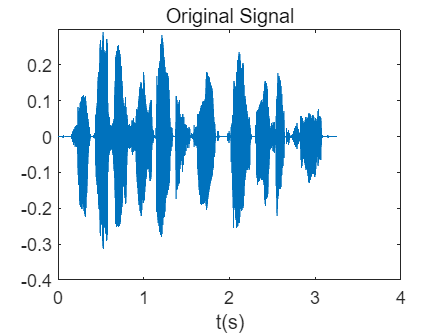

[x1,~]=audioread('.\resource\C_01_01.wav');
[x2,fs]=audioread('.\resource\C_01_02.wav');

fcut=50;

plot(xTime(x1,fs),x1),title('Original Signal'),xlabel('t(s)')

SSN=createSSN(x1,fs);

Frequency-to-place mapping in cochlea:


$$f=165\ldotp 4\times \left({10}^{0\ldotp 06\cdot d} -1\right)$$


where $f$ is -3 dB cut-off frequency, and $d$ is the distance (in millimeter) along the cochlea.

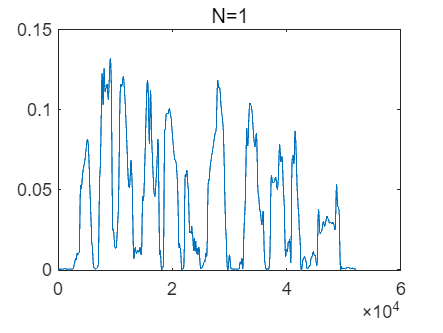

y1=extractEnvelope(x1,1,50,fs);
%信号x1，N=1，fcut=50，采样频率fs
y2=extractEnvelope(x1,2,50,fs);
y4=extractEnvelope(x1,4,50,fs);
y6=extractEnvelope(x1,6,50,fs);
y8=extractEnvelope(x1,8,50,fs);

plot(y1),title('N=1')

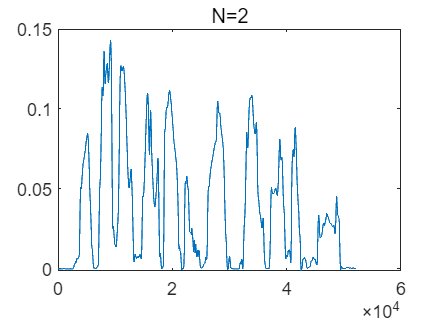

plot(y2),title('N=2')

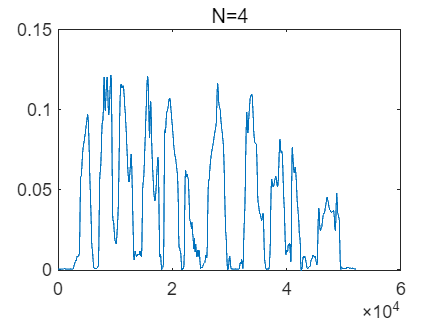

plot(y4),title('N=4')

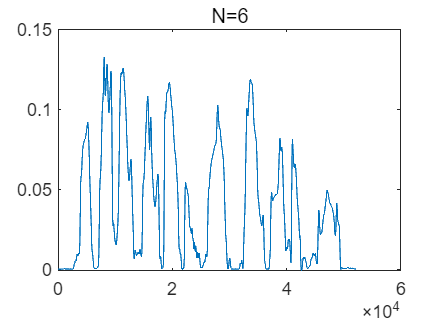

plot(y6),title('N=6')

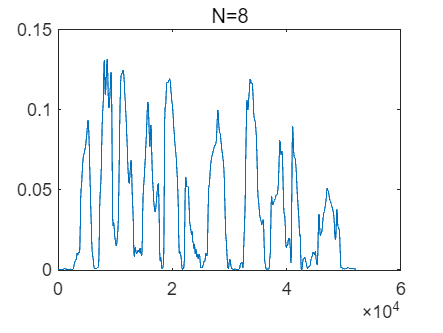

plot(y8),title('N=8')

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function SSN=createSSN(x,fs)%上节课做的生成SSN
    x=x';
    sig=repmat(x,1,10);
    nfft=512;
    [Pxx,w]=pwelch(sig,hamming(nfft),nfft/2,nfft,fs);
    b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
    white_noise=1-2*rand(1,length(x)+3000);
    SSN=filter(b,1,white_noise);
    SSN=SSN(2000:end);
    %Discard the beginning which has little sound.
    SSN=SSN(1:length(x));
end

function Fs=createBandDivision(N)

    %输入想要获得多少个带
    %Fs是每个带的频率区间，每个元素都是二元素向量
    fmin=200;
    fmax=7000;
    dmin=log10(fmin/165.4+1)/0.06;
    dmax=log10(fmax/165.4+1)/0.06;
    D=linspace(dmin,dmax,N+1);
    F=zeros(1,N+1);
    for k=1:N+1
        F(k)=165.4*(10^(0.06*D(k))-1);
    end
    Fs=zeros(N,2);
    for k=1:N
        Fs(k,:)=[F(k),F(k+1)];
    end
end

function y=extractEnvelope(x,N,fcut,fs)
    %输入音频x，切割带数N
    Fs=createBandDivision(N);
    for k=1:N
        if k==1
            y=zeros(length(x),1);
            %TODO:如果以后要转置x，记得修改这里
        end
        [b,a]=butter(4,Fs(k,:)/(fs/2),"bandpass");
        %阶数n=4
        y_filtered=filter(b,a,x);

        [b,a]=butter(4,fcut/(fs/2),'low');
        %低通滤波取得包络，阶数为4
        y_env=filter(b,a,abs(y_filtered));

        y=y+y_env;
        y=y./norm(y).*norm(x);
    end
end